# Activity 6: Morphological Operations

#### Jonabel Eleanor B. Baldres

#### App Physics 157 WFY FX 2

## Activity 6.1

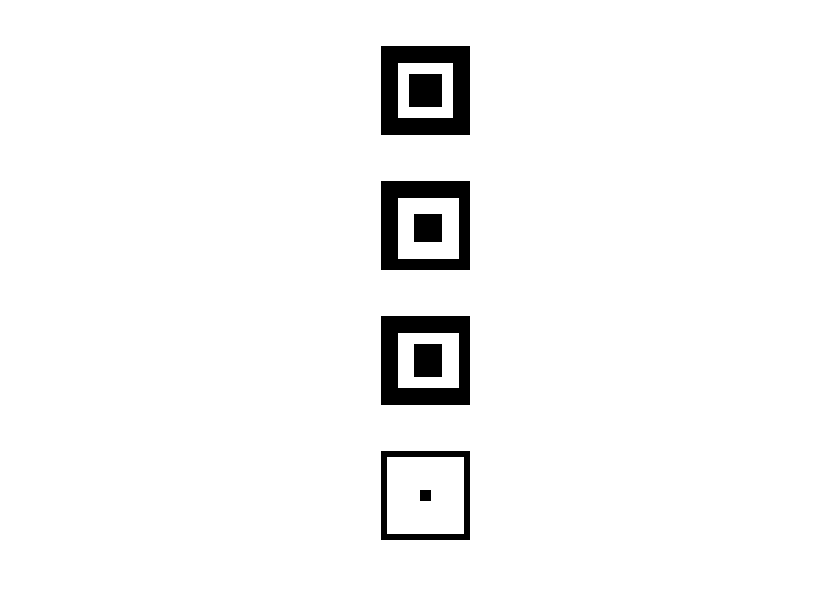

dilate_hollow;

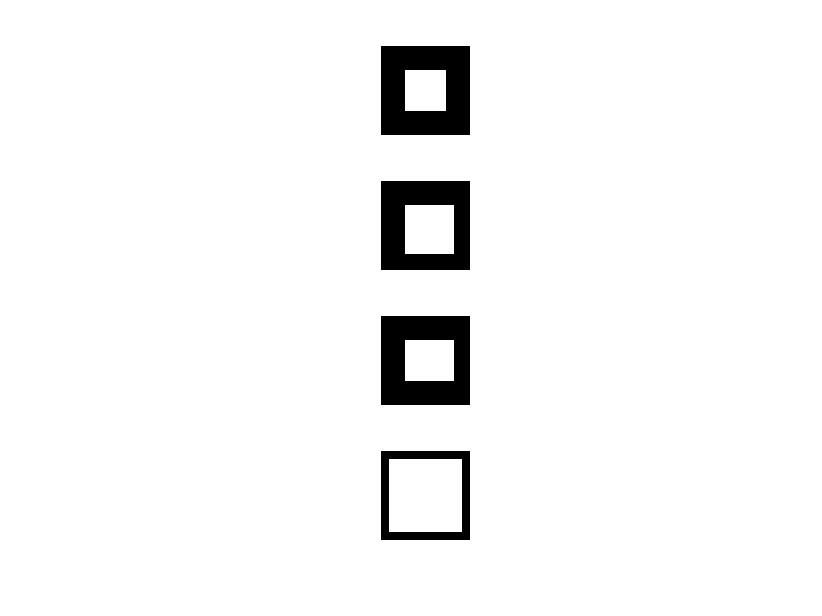

dilate_square;

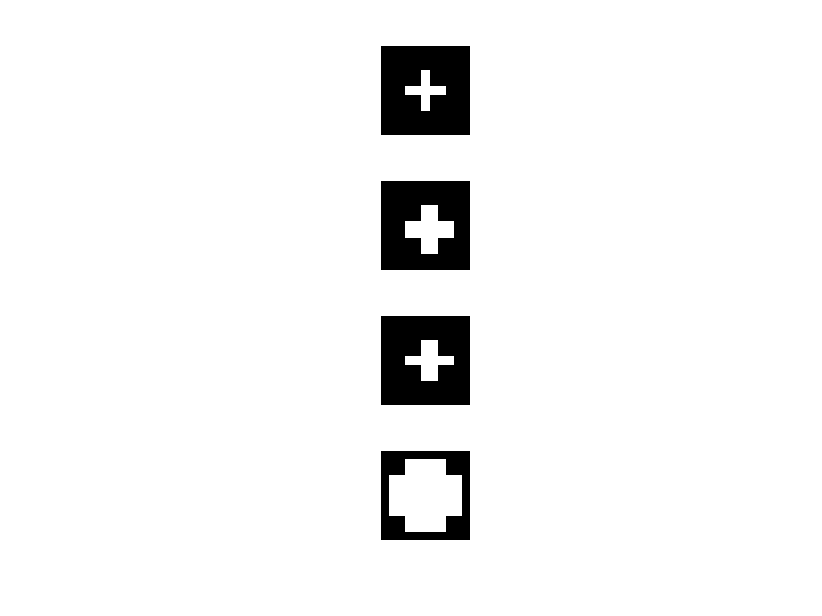

dilate_cross;

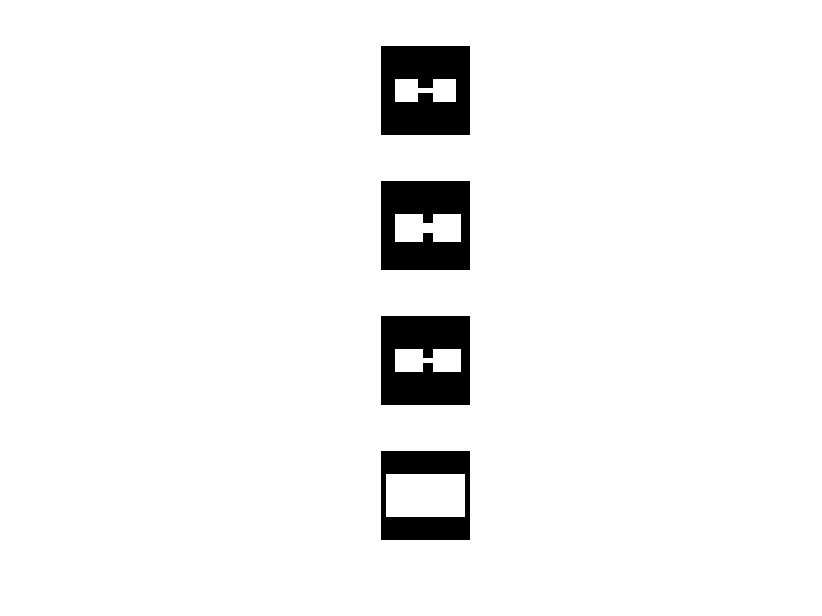

dilate_dumbbell;

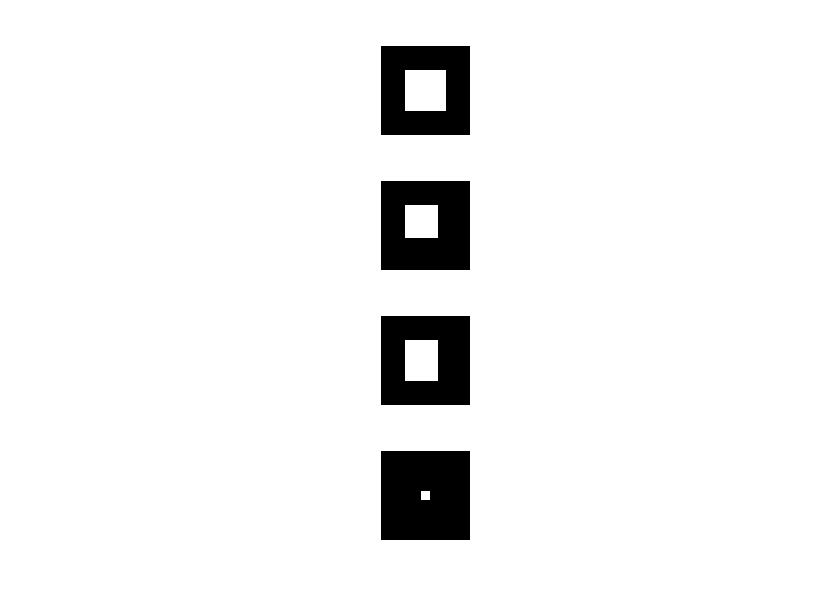

erode_square;

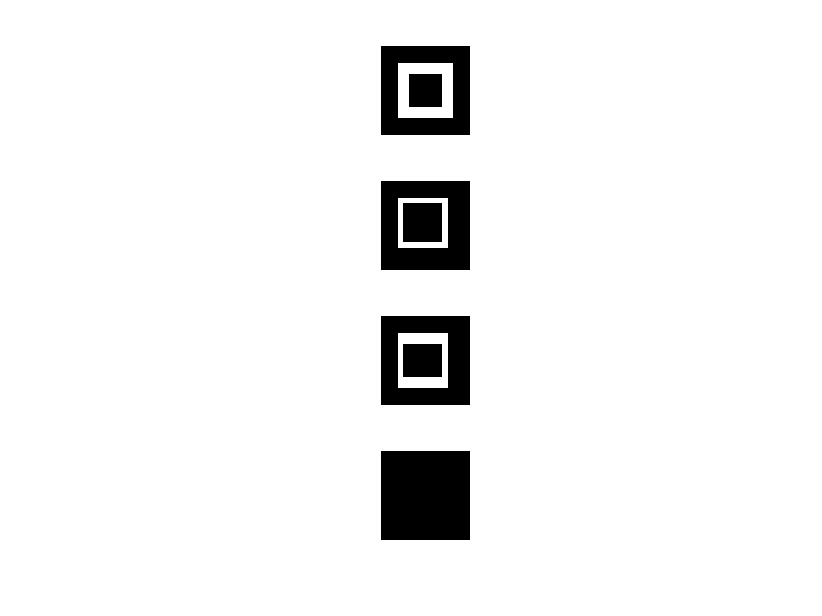

erode_hollow;

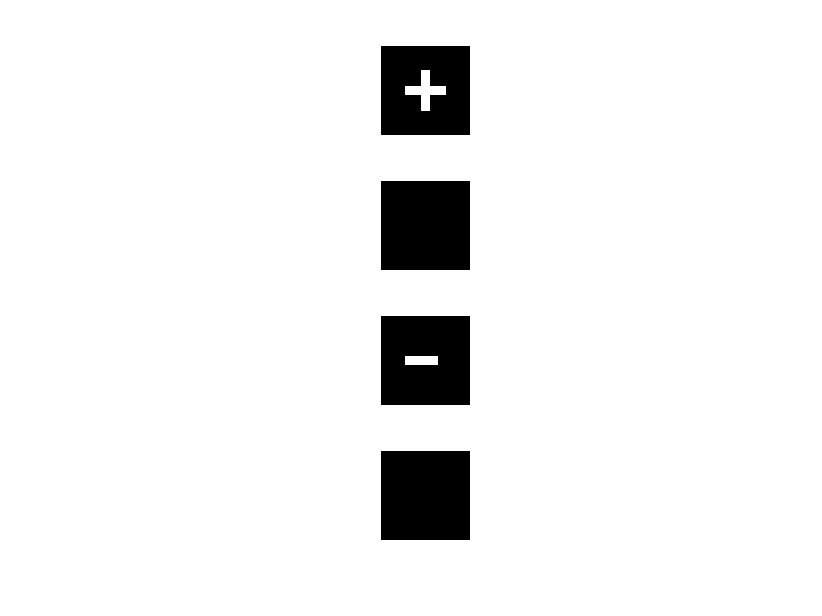

erode_cross;

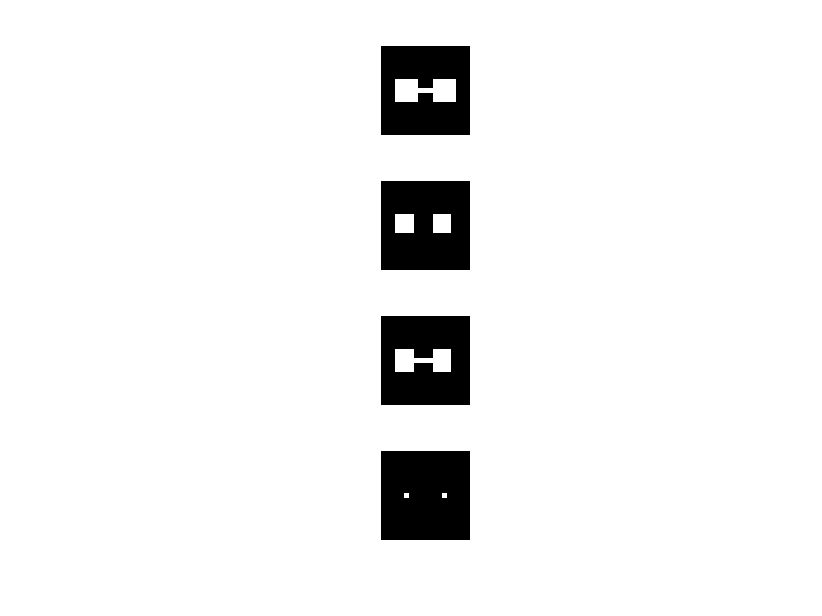

erode_dumbbell;

## Activity 6.2

clear all; 

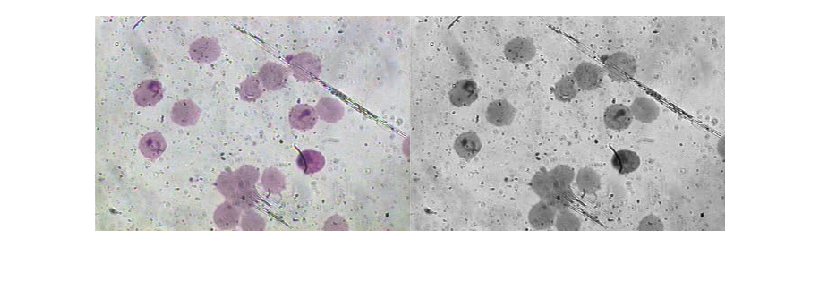

ans =    240   352


ans =    240   352     3


I = imread("malaria(1).jpeg");
Igray = rgb2gray(I);
figure;
imshowpair(I, Igray, "montage");
saveas(gcf, 'cells_orig_gray.jpeg')

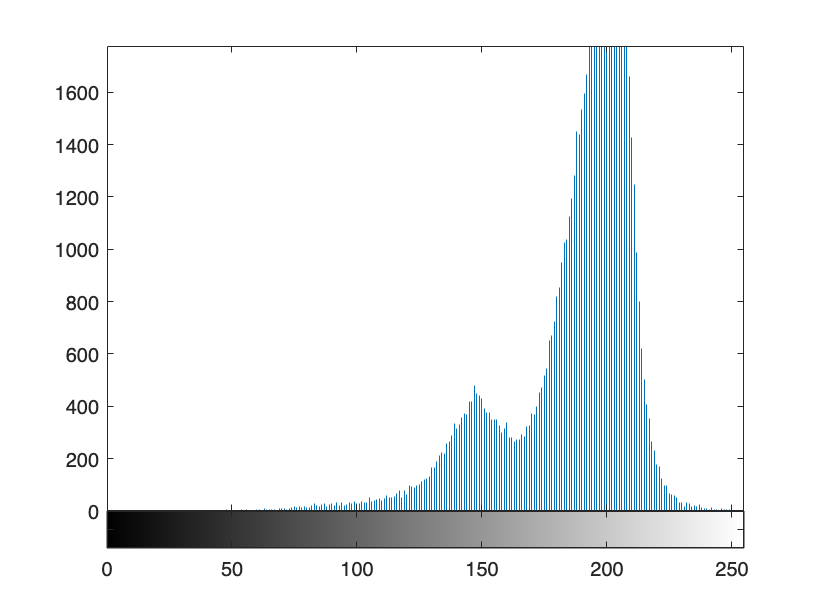

figure; imhist(Igray); 
saveas(gcf, 'hist_cells_gray.jpeg')

%imtool(Igray);

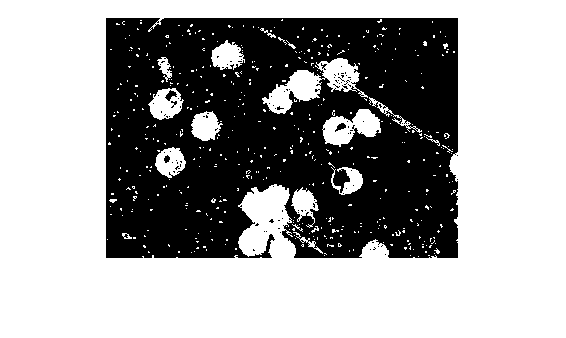

%thresholding
BW= and(Igray < 164, Igray> 100);
figure; imshow(BW);
saveas(gcf, 'thresholded_gray.jpeg')

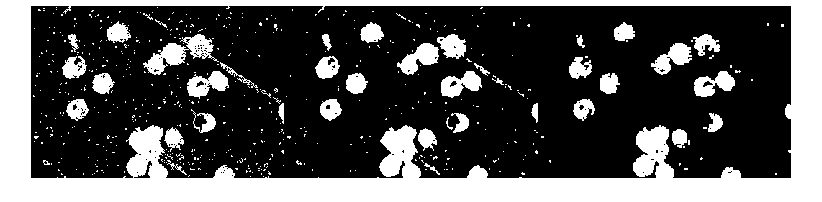


%bwmorph
BW2 = bwmorph(BW, 'majority');
BW3 = bwmorph(BW, 'open');
montage([BW, BW2, BW3], 'size', [1 NaN]);
saveas(gcf, 'bwmorph.jpeg')

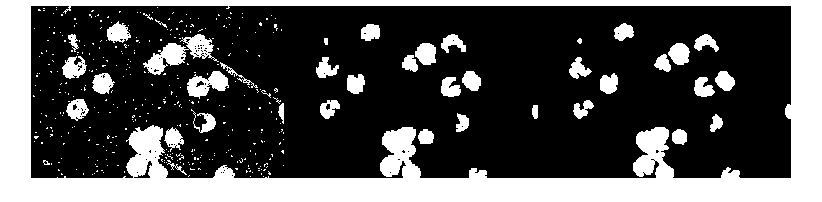


%structural elements
SE_3 = strel('disk', 3);
SE_4 = strel('disk', 4);

%open
BW4 = imopen(BW,SE_3);
BW5 = imopen(BW,SE_4);
montage([BW, BW4, BW5], 'size', [1 NaN]);
saveas(gcf, 'open.jpeg')

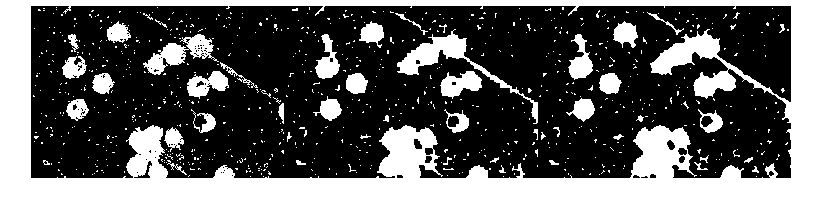


%close
BW6 = imclose(BW, SE_3);
BW7 = imclose(BW,SE_4);
montage([BW, BW6, BW7], 'size', [1 NaN]);
saveas(gcf, 'close.jpeg')

From the images above, we can see that BW4 performed the best in isolating the cells. With that, we use it in the succeeding steps. 

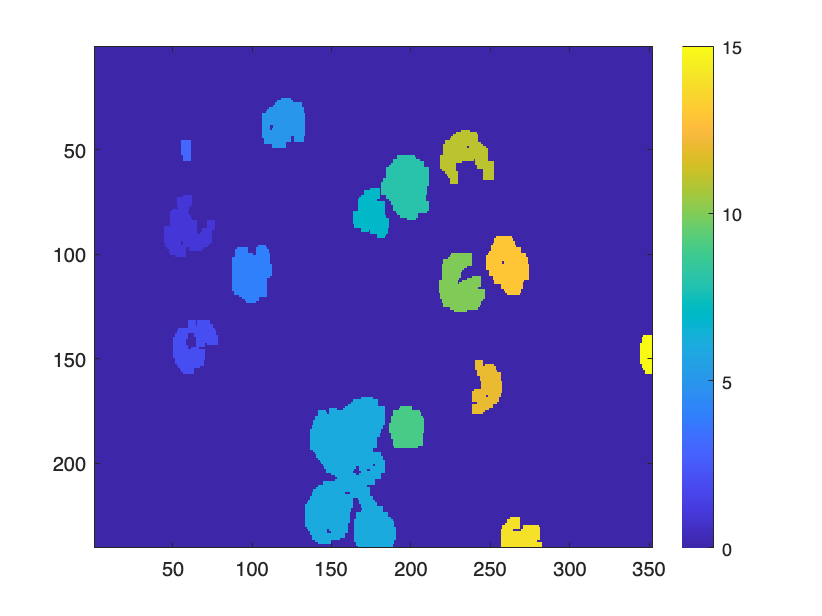

BWL = bwlabel(BW4);
figure; imagesc(BWL); colorbar
saveas(gcf, 'bw4.jpeg')

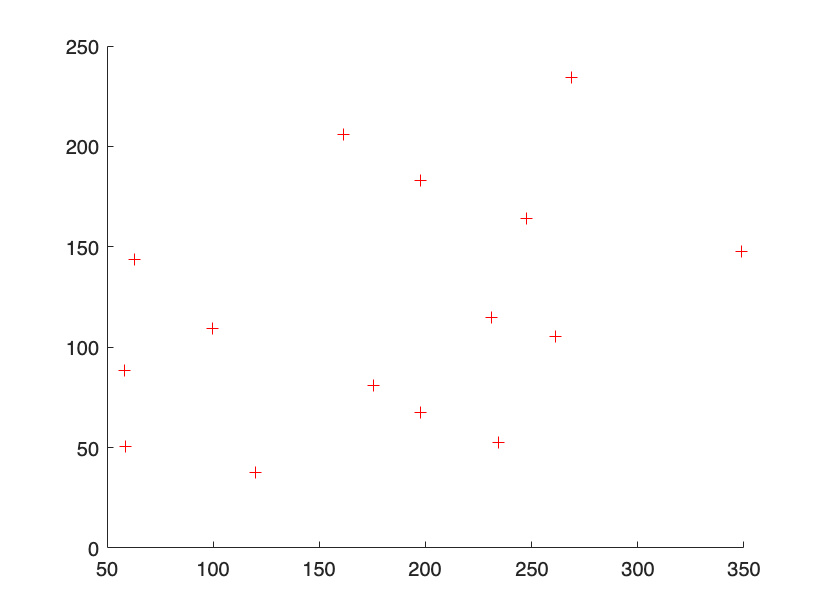

features = regionprops(BWL);
%computes the properties of the connected components in BWL and stores it
%in features

%Putting label number on centroid of blobs
centroid = cat(1,features.Centroid);
figure; hold on;
plot(centroid(:,1), centroid(:,2), 'r+')
saveas(gcf, 'centroid_label.jpeg')

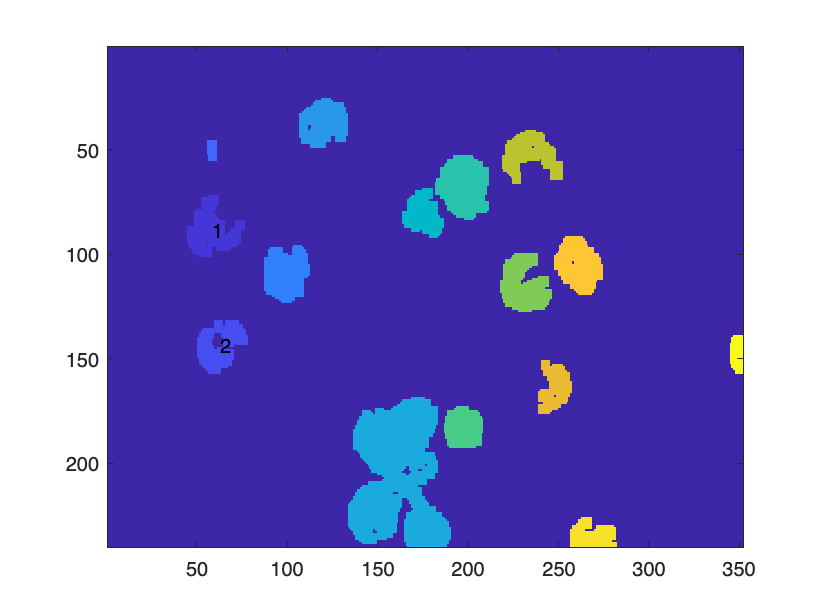


%Placing label nunbers on centroid of blobs
figure; imagesc(BWL); hold on;
for i = 1:size(centroid,2)
    text(centroid(i,1), centroid(i,2), num2str(i));
end
saveas(gcf, 'label_numbers.jpeg')

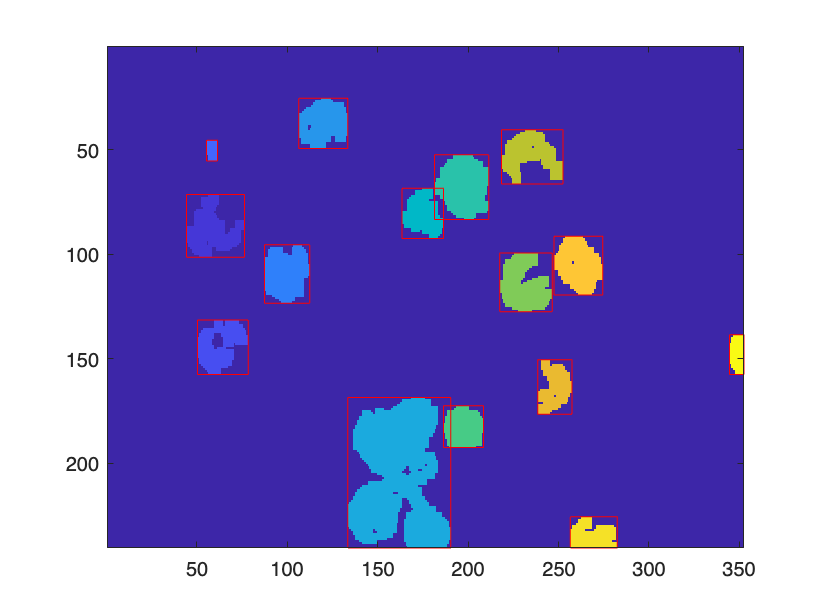


%placing bounding boxes around each blob
figure; imagesc(BWL); hold on;
bb = cat(1,features.BoundingBox);
for i = 1:size(features,1)
    rectangle('Position',bb(i,:),'EdgeColor','r');
end
saveas(gcf, 'bounding_box.jpeg')

## Functions

%square
function A= square()
    A = zeros(11,11);
    A(4:8,4:8) = 1;
end

% hollow
function A = hollow()
    A = zeros(16, 16); 
    start = 4;
    ending = 13;
    A(start:ending, start:ending) = 1;
    A(start+2:ending-2, start+2:ending-2) = 0;
end

%cross
function A = cross()
    A = zeros(11,11);
    A(4:8,4:8) = 1;
    A(4:5,4:5) = 0;
    A(7:8,7:8) = 0;
    A(4:5,7:8) = 0;
    A(7:8,4:5) = 0;
end

%dumbbell
function A= dumbbell()
    A = zeros(19,19);
    A(8:12,4:16) = 1;
    A(8:9,9:11) = 0;
    A(8:9,9:11) = 0;
    A(11:12,9:11) = 0;
end

%dilation_of_square
function [dilate_0,dilate_1,dilate_2,dilate_3] = dilate_square();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    dilate_0 = square();
    dilate_1= imdilate(square(),two_by_two);
    dilate_2 = imdilate(square(),two_by_one);
    dilate_3 = imdilate(square(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(dilate_0);
    subplot(4,1,2);
    imshow(dilate_1);
    subplot(4,1,3);
    imshow(dilate_2);
    subplot(4,1,4);
    imshow(dilate_3);
end


%dilation of a hollow square
function [dilate_0,dilate_1,dilate_2,dilate_3] = dilate_hollow();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    dilate_0 = hollow();
    dilate_1= imdilate(hollow(),two_by_two);
    dilate_2 = imdilate(hollow(),two_by_one);
    dilate_3 = imdilate(hollow(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(dilate_0);
    subplot(4,1,2);
    imshow(dilate_1);
    subplot(4,1,3);
    imshow(dilate_2);
    subplot(4,1,4);
    imshow(dilate_3);
end

%dilation of cross
function [dilate_0,dilate_1,dilate_2,dilate_3] = dilate_cross();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    dilate_0 = cross();
    dilate_1= imdilate(cross(),two_by_two);
    dilate_2 = imdilate(cross(),two_by_one);
    dilate_3 = imdilate(cross(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(dilate_0);
    subplot(4,1,2);
    imshow(dilate_1);
    subplot(4,1,3);
    imshow(dilate_2);
    subplot(4,1,4);
    imshow(dilate_3);
end

%dilation of dumbbell
function [dilate_0,dilate_1,dilate_2,dilate_3] = dilate_dumbbell();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    dilate_0 = dumbbell();
    dilate_1= imdilate(dumbbell(),two_by_two);
    dilate_2 = imdilate(dumbbell(),two_by_one);
    dilate_3 = imdilate(dumbbell(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(dilate_0);
    subplot(4,1,2);
    imshow(dilate_1);
    subplot(4,1,3);
    imshow(dilate_2);
    subplot(4,1,4);
    imshow(dilate_3);
end

%erosion of a square
function [erode_0,erode_1,erode_2,erode_3] = erode_square();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    erode_0 = square();
    erode_1= imerode(square(),two_by_two);
    erode_2 = imerode(square(),two_by_one);
    erode_3 = imerode(square(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(erode_0);
    subplot(4,1,2);
    imshow(erode_1);
    subplot(4,1,3);
    imshow(erode_2);
    subplot(4,1,4);
    imshow(erode_3);
end

%erosion of a hollow
function [erode_0,erode_1,erode_2,erode_3] = erode_hollow();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    erode_0 = hollow();
    erode_1= imerode(hollow(),two_by_two);
    erode_2 = imerode(hollow(),two_by_one);
    erode_3 = imerode(hollow(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(erode_0);
    subplot(4,1,2);
    imshow(erode_1);
    subplot(4,1,3);
    imshow(erode_2);
    subplot(4,1,4);
    imshow(erode_3);
end

%erosion of a cross
function [erode_0,erode_1,erode_2,erode_3] = erode_cross();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    erode_0 = cross();
    erode_1= imerode(cross(),two_by_two);
    erode_2 = imerode(cross(),two_by_one);
    erode_3 = imerode(cross(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(erode_0);
    subplot(4,1,2);
    imshow(erode_1);
    subplot(4,1,3);
    imshow(erode_2);
    subplot(4,1,4);
    imshow(erode_3);
end

%erosion of a dumbbell
function [erode_0,erode_1,erode_2,erode_3] = erode_dumbbell();
    %structural elements
    two_by_two = strel([1 1; 1 1]);
    two_by_one= strel(circshift([1 1], [0, -1])); 
    five_by_five = strel([1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1 ]);

    erode_0 = dumbbell();
    erode_1= imerode(dumbbell(),two_by_two);
    erode_2 = imerode(dumbbell(),two_by_one);
    erode_3 = imerode(dumbbell(), five_by_five);
    figure;
    subplot(4,1,1);
    imshow(erode_0);
    subplot(4,1,2);
    imshow(erode_1);
    subplot(4,1,3);
    imshow(erode_2);
    subplot(4,1,4);
    imshow(erode_3);
end
